clear variables;

% this is a tutorial script for introduction to graph theory

help graph;

 graph Undirected Graph
    G = graph builds an empty graph with no nodes and no edges.
 
    G = graph(A) uses the square symmetric matrix A as an adjacency matrix
    and constructs a weighted graph with edges corresponding to the nonzero
    entries of A. The weights of the edges are taken to be the nonzero
    values in A. If A is logical then no weights are added.
 
    G = graph(A,NAMES) additionally uses NAMES as the names of
    the nodes in G. NAMES must be a string vector or a cell array of
    character vectors, and must have as many elements as size(A,1).
 
    G = graph(A,...,TYPE) uses only a triangle of A to construct the graph.
    TYPE can be:
            'upper'  -  Use the upper triangle of A.
            'lower'  -  Use the lower triangle of A.
 
    G = graph(A,...,'omitselfloops') ignores the diagonal entries of the
    adjacency matrix A and does not add self-loo

## create a graph

the easiest way to create a graph in MATLAB is by using the adjacency matrix. let's create a 10 node graph

n=10; % # of nodes
A=zeros(n); % initialize the Adjacency matrix

% let's create a complete undirected graph. which means every node is
% connected to every other node. we will do this in for loops

for ii=1:n % for each node
    % for each node after ii (this is because Adjacency matrix is symmetric
    % and we can simply add the upper and lower diagonals later)
    for jj=ii+1:n
        A(ii,jj)=1; % they are connected
    end
end

A

A =      0     1     1     1     1     1     1     1     1     1
     0     0     1     1     1     1     1     1     1     1
     0     0     0     1     1     1     1     1     1     1
     0     0     0     0     1     1     1     1     1     1
     0     0     0     0     0     1     1     1     1     1
     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     1     1     1
     0     0     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0



% this is where we make the matrix symmetric by adding the transpose
A=A+A'

A =      0     1     1     1     1     1     1     1     1     1
     1     0     1     1     1     1     1     1     1     1
     1     1     0     1     1     1     1     1     1     1
     1     1     1     0     1     1     1     1     1     1
     1     1     1     1     0     1     1     1     1     1
     1     1     1     1     1     0     1     1     1     1
     1     1     1     1     1     1     0     1     1     1
     1     1     1     1     1     1     1     0     1     1
     1     1     1     1     1     1     1     1     0     1
     1     1     1     1     1     1     1     1     1     0


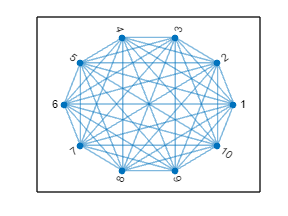


% create a graph
G=graph(A);

% plot the graph
figure(1); gcf; clf;
plot(G, 'layout', 'circle');

## plot another graph

Buckminster Fuller geodesic dome, which is also in the shape of a soccer ball or a carbon-60 molecule.

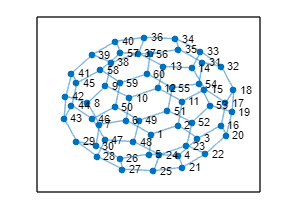

G=graph(bucky);
figure(2); gcf; clf;
plot(G)

## node degree

deg=degree(G)

deg =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3



% use this to create the degree matrix
D=diag(deg)

D =      3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0   

% get the adjacency matrix
% this gives the sparse form
A=adjacency(G)

A =    (2,1)        1
   (5,1)        1
   (6,1)        1
   (1,2)        1
   (3,2)        1
  (11,2)        1
   (2,3)        1
   (4,3)        1
  (16,3)        1
   (3,4)        1
   (5,4)        1
  (21,4)        1
   (1,5)        1
   (4,5)        1
  (26,5)        1
   (1,6)        1
   (7,6)        1
  (10,6)        1
   (6,7)        1
   (8,7)        1
  (30,7)        1
   (7,8)        1
   (9,8)        1
  (42,8)        1
   (8,9)        1
  (10,9)        1
  (38,9)        1
   (6,10)       1
   (9,10)       1
  (12,10)       1
   (2,11)       1
  (12,11)       1
  (15,11)       1
  (10,12)       1
  (11,12)       1
  (13,12)       1
  (12,13)       1
  (14,13)       1
  (37,13)       1
  (13,14)       1
  (15,14)       1
  (33,14)       1
  (11,15)       1
  (14,15)       1
  (17,15)       1
   (3,16)       1
  (17,16)       1
  (20,16)       1
  (15,17)       1
  (16,17)       1
  (18,17)       1
  (17,18)       1
  (19,18)       1
  (32,18)       1
  (18,19)       1
  (20,


% to get the full form, type
% A=full(A);

L=laplacian(G);

## let's work with another type of graph

this creates a square lattice with 8 nodes on each side

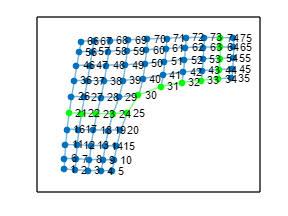

n = 10;
A = delsq(numgrid('L',n+2));
G = graph(A,'OmitSelfLoops');
G.Edges.Weight = ones(numedges(G),1);
figure(1); gcf; clf;
h = plot(G);

% get the node degree
deg=degree(G);

% highlight the shortest path between 74 and 21
path = shortestpath(G,74,21);
highlight(h,path,'NodeColor','g','EdgeColor','g')

## a type of random graph

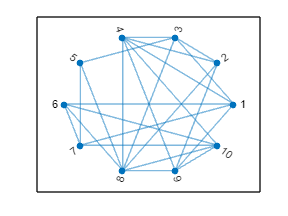

n=10;
p=.5; % probability of an edge between any two nodes

% let's create a complete undirected graph. which means every node is
% connected to every other node.

% generate a random number and if it is less than p then make an
% edge
A=rand(n)<p;
A=triu(A)+triu(A)';
A=A-diag(diag(A));

% can alternatively do this in a for loop
% A=zeros(n);
% for ii=1:n
%     for jj=ii+1:n
%         if rand < p
%             A(ii,jj)=1; % they are connected
%         end
%     end
% end
% this is where we make the matrix symmetric by adding the transpose
% A=A+A';

% create a graph
G=graph(A);

% plot the graph
figure(1); gcf; clf;
plot(G, 'layout', 'circle');

## network properties (reachability)

% help distances
geo=distances(G);

% to avoid counting self-distances
for ii=1:n
    geo(ii,ii)=nan;
end

% characteristic path length
L=1/(n*(n-1))*nansum(nansum(geo))

L = 1.4889


% harmonic mean
E=1/(n*(n-1))*nansum(nansum(1./geo))

E = 0.7630

## network properties (connectivity)

deg=degree(G);
mean(deg)

ans = 4.8000

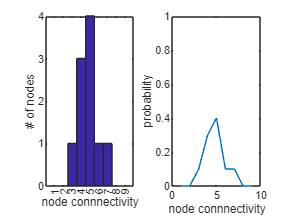


% degree distributions
figure(2); gcf; clf;
subplot(1,2,1);
hist(deg, 1:n-1);
xlabel('node connnectivity');
ylabel('# of nodes');
% show in the form of P(k)
[N, k]=hist(deg, 1:n-1);
% this makes sure that the sum(P(k))=1
Pk=N/sum(N);
subplot(1,2,2);
plot(k, Pk);

% set the limits from 0 to 1 so that we compare properly
set(gca, 'ylim', [0 1]);

xlabel('node connnectivity');
ylabel('probability');

% laplacian
L=laplacian(G);
lambda=eig(L);
lambda(1)

ans = -1.4218e-15

lambda(2)

ans = 2.3836

% number of connected components = C
% rank of L = N-C
rank(full(L))

ans = 9

conn=n-rank(full(L))

conn = 1


% first and second moments
% first moment, same as mean
sum(k.*Pk)

ans = 4.8000


% second moment, same as variance
% note the high value showing that this graph has very high and low
% connected nodes
sum(k.^2.*Pk)

ans = 24.2000


% check
max(deg)

ans = 7

min(deg)

ans = 3

## more network properties

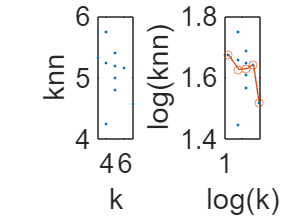

% correlation
% the second argument is the dimension of the matrix, which is rows in this
% case

N=size(A,1);

% the node degree
% sum along columns
k=sum(A,2);

figure(2); gcf; clf;

knn=zeros(numel(k),1);
for i=1:N
    % vectorize the sum aij*kj
    % j are all the columns
    knn(i)=sum(A(i,:).*k')/k(i);
end



subplot(1,2,1); gca;
% plot knn against k
plot(k, knn, '.');
set(gca, 'fontsize', 20);
xlabel('k');
ylabel('knn');

subplot(1,2,2); gca;
% this creates a loglog plot
plot(log(k), log(knn), '.');
hold on;
krv=unique(k)';
for jj=krv
    mean_knn(jj==krv)=mean(knn(k==jj));
end
plot(log(krv), log(mean_knn), '-o');
% errorbar(krv, mknn, sknn, 'k', 'linewidth', 2);
set(gca, 'fontsize', 20);

xlabel('log(k)');
ylabel('log(knn)');